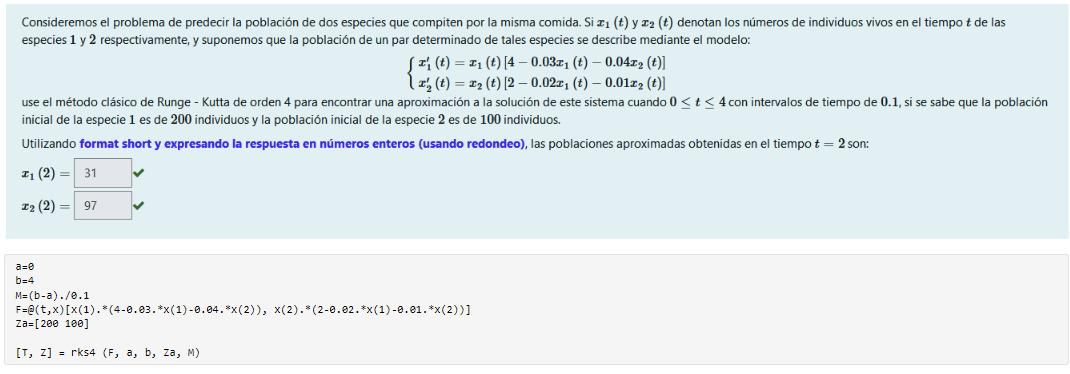

a= 0; b= 4; h=0.1; M = 4/h;
F = @(t,x) [x(1)*(4-0.03*x(1)-0.04*x(2)), x(2)*(2-0.02*x(1)-0.01*x(2))];
Za = [200 100];
[T, Z] = rks4 (F, a, b, Za, M);
[T', Z] % Son 31 y 97

En este caso tengo un SISTEMA DE ECUACIONES DIFERENCIALES. PARA ELLO, SE APLICA LAS RUTINAS PARA SISTEMAS.

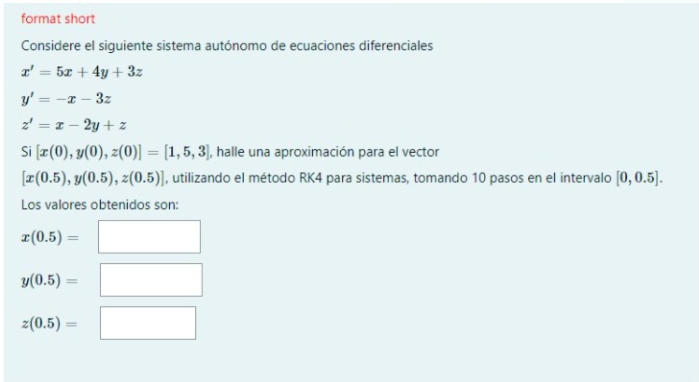

F = @(t,U) [5*U(1)+4*U(2)+3*U(3) , -U(1)-3*U(3)  , U(1)-2*U(2)+U(3) ];
Za = [1 5 3]; % Condiciones iniciales para cada una de las ED
a = 0;
b = 0.5;
M = 10; % Numero sub intervalos

[T, Z] = rks4 (F, a, b, Za, M);
[T',Z]

Las soluciones pedidas son:

x(0.5) = U1(0.5) = 57.6384

Y(0.5) = -13.3050

Z(0.5) = 16.2481

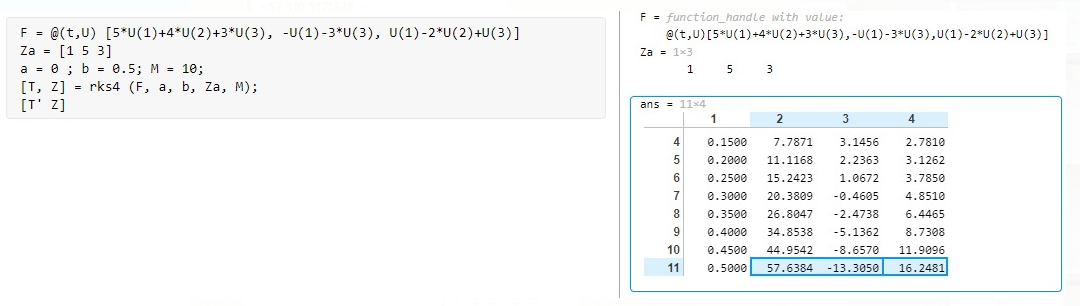

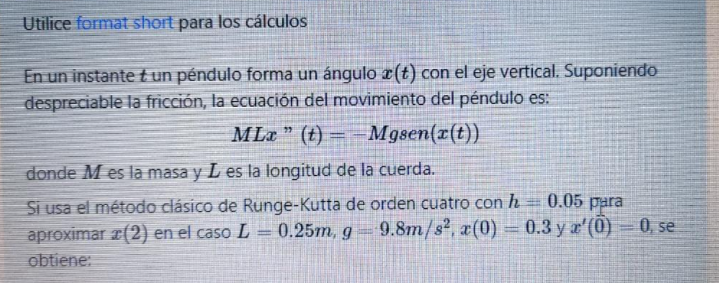

h=0.05; a= 0; b= 2; M = b/h;

F = @(t,U) [U(2), -9.8*sin(U(1))/0.25]
Za = [0.3 0] % Condicion inicial

AproxSol = vectorialSystem(F, a, b, Za, 40, "RK4")

Para RK4 vectorial (Es con derivadas de orden superior) se hace asi. Tambien se usa el codigo rsk4 de abajo. En ambos, el resultado coincide

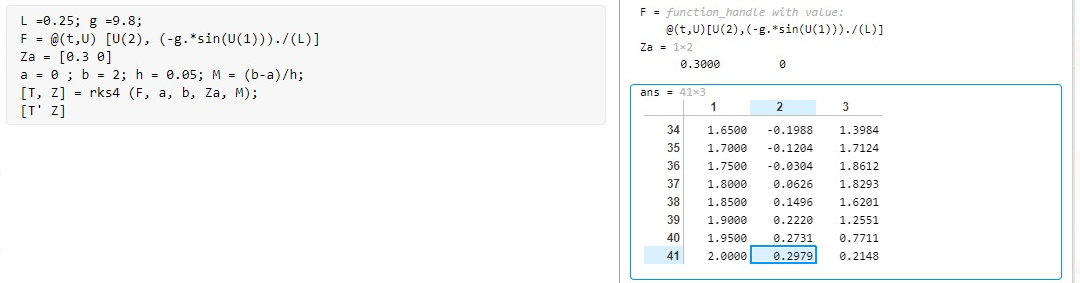

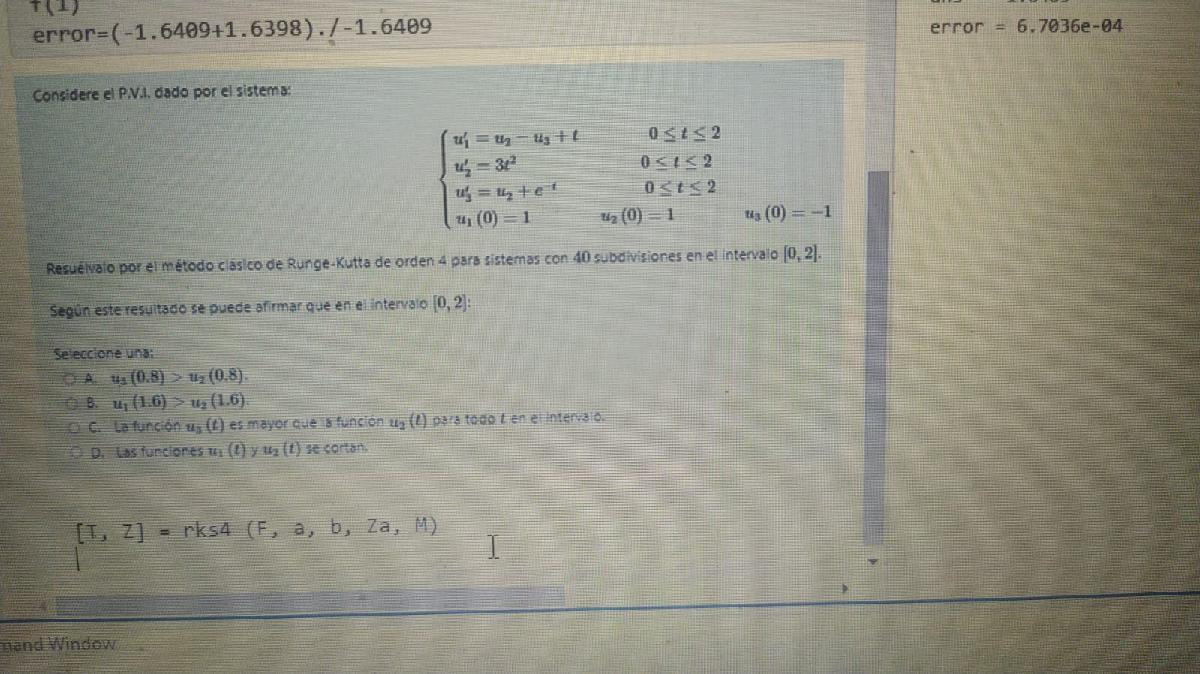

a= 0; b=2; M = 40;
F = @(t,U) [U(2)-U(3)+t, 3*t^2, U(2)+exp(-t) ]
Za = [1 1 -1]
AproxSol = vectorialSystem(F, a, b, Za, 40, "RK4")


plot(T,Z(:,1))
hold on
plot(T,Z(:,2))


Efectivamente, se cortan.

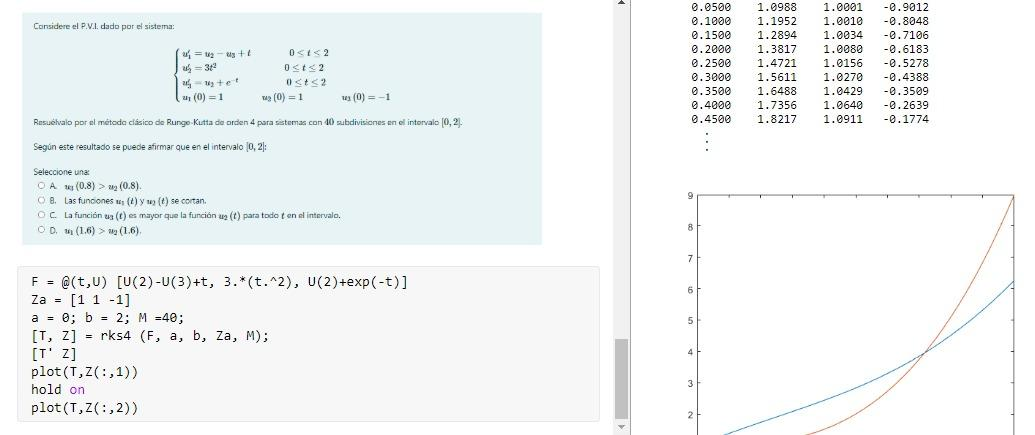

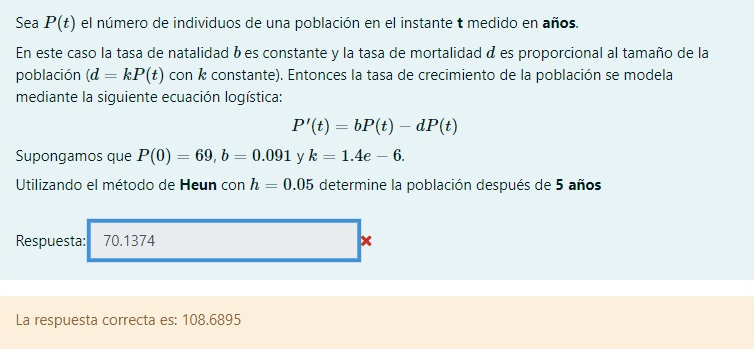

a=0; b=5; h=0.05; M=(b-a)/h; ya=69;
f= @(t,y) [0.091*y-1.4e-6*y^2]
H = heun (f, a, b, ya, M)
% MELISIMO

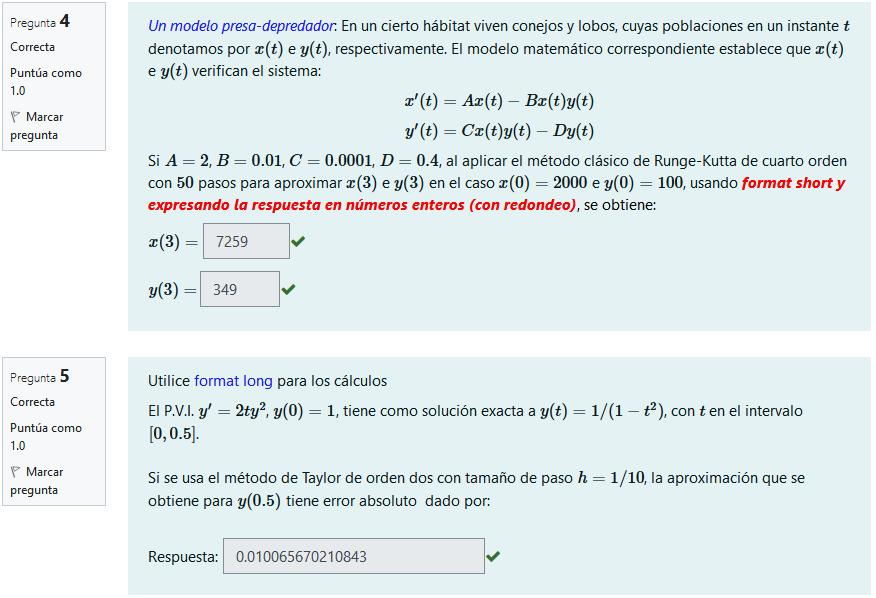

a=0; b=3; za= [2000,100]; M=50;
F = @(t,u) [2*u(1)-0.01*u(2)*u(1) , 0.0001*u(1)*u(2)-0.4*u(2)]

F = function_handle with value:
    @(t,u)[2*u(1)-0.01*u(2)*u(1),0.0001*u(1)*u(2)-0.4*u(2)]


AproxSol = vectorialSystem(F, a, b, za, M,"RK4") % Melo, pero ojo que la dieron en decimales

AproxSol = 	1.0e+04 *

         0    0.2000    0.0100
    0.0000    0.2124    0.0099
    0.0000    0.2258    0.0098
    0.0000    0.2402    0.0097
    0.0000    0.2556    0.0096
    0.0000    0.2721    0.0095
    0.0000    0.2898    0.0094
    0.0000    0.3088    0.0094
    0.0000    0.3292    0.0093
    0.0001    0.3510    0.0093


syms t y
f =  2*t*y^2

$$f = 2\,t\,y^{2}$$

format long
a=0; b=0.5; h=1/10; M = 0.5/h; ya=1;
T = taylorN(f,2, a, b, ya, M)

T =                    0   1.000000000000000
   0.100000000000000   1.010000000000000
   0.200000000000000   1.041015120400000
   0.300000000000000   1.097005802171127
   0.400000000000000   1.185997901503881
   0.500000000000000   1.323267663122490


solucion = T(end,2)

solucion =    1.323267663122490


en y(0.5) me da 1.3233

y = @(t) 1./(1-t.^2);
abs(y(0.5)-solucion) % MELISIMO

ans =    0.010065670210843


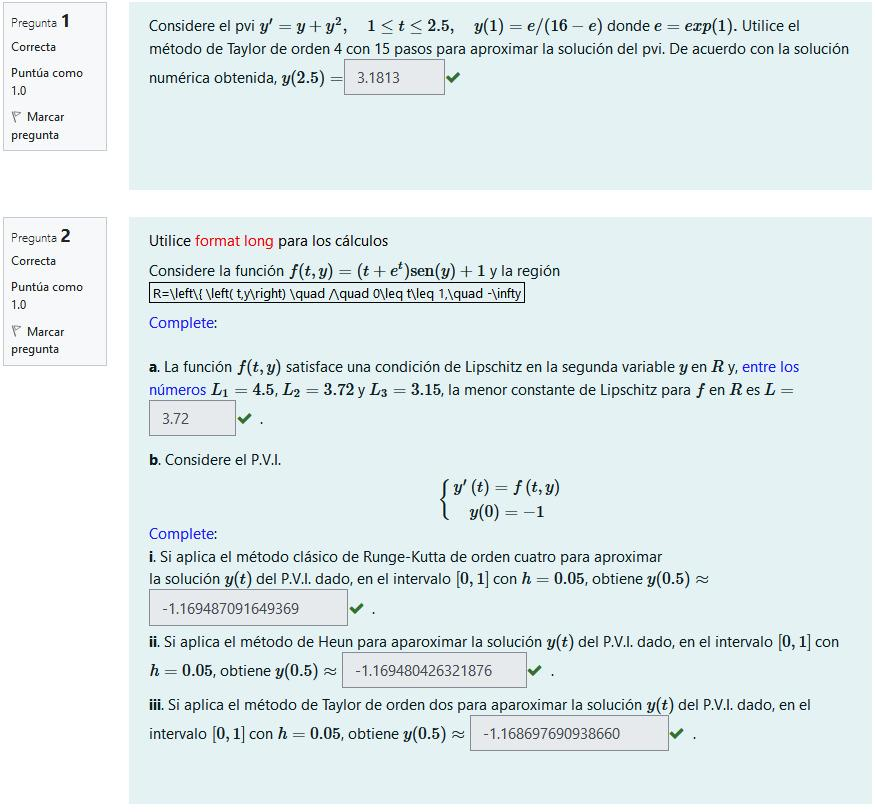

% Primer ejercicio
a=1; b=2.5;M=15;
syms t y
f = y+y^2

$$f = y^{2}+y$$

ya= exp(1)/(16-exp(1))

ya = 0.2047

format short
T = taylorN(f,4, a, b, ya, M) % Melisimo 

T =     1.0000    0.2047
    1.1000    0.2312
    1.2000    0.2618
    1.3000    0.2976
    1.4000    0.3395
    1.5000    0.3891
    1.6000    0.4484
    1.7000    0.5200
    1.8000    0.6080
    1.9000    0.7178


% Segundo ejercicio a) calcule liptchetz
% b)
F = @(t,y) (t+exp(t))*sin(y)+1

F = function_handle with value:
    @(t,y)(t+exp(t))*sin(y)+1


a=0; b=1; h=0.05; M=b/h; ya=-1;
format long 
H = heun (F, a, b, ya, M)

H =                    0  -1.000000000000000
   0.050000000000000  -0.994099600302804
   0.100000000000000  -0.992386582778066
   0.150000000000000  -0.995099710510621
   0.200000000000000  -1.002530079983431
   0.250000000000000  -1.015024559862012
   0.300000000000000  -1.032987806026530
   0.350000000000000  -1.056881749576621
   0.400000000000000  -1.087220935633219
   0.450000000000000  -1.124561446140895


 R = rk4 (F, a, b, ya, M)

R =                    0  -1.000000000000000
   0.050000000000000  -0.994099948976505
   0.100000000000000  -0.992387354431984
   0.150000000000000  -0.995100990050942
   0.200000000000000  -1.002531960991258
   0.250000000000000  -1.015027139887867
   0.300000000000000  -1.032991177635612
   0.350000000000000  -1.056885985326282
   0.400000000000000  -1.087226065104255
   0.450000000000000  -1.124567423854011


F1= (t+exp(t))*sin(y)+1

$$F1 = \sin\left(y\right)\,\left(t+{\mathrm{e}}^{t}\right)+1$$

 T = taylorN(F1,2, a, b, ya, M) % MELISIMO

T =                    0  -1.000000000000000
   0.050000000000000  -0.994070159711845
   0.100000000000000  -0.992318973607772
   0.150000000000000  -0.994984017911872
   0.200000000000000  -1.002355191003325
   0.250000000000000  -1.014778265431711
   0.300000000000000  -1.032657095792235
   0.350000000000000  -1.056453411549356
   0.400000000000000  -1.086682609074826
   0.450000000000000  -1.123903307250494


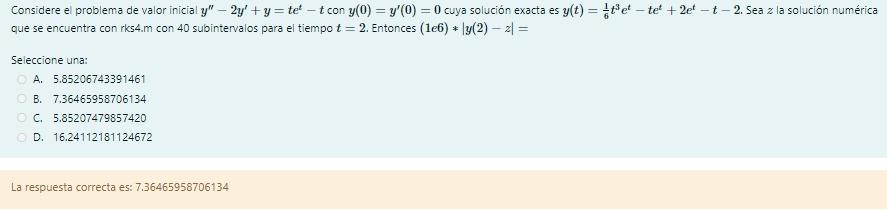

 a=0;b=2;M=40;Za=[0 0];
 F=@(t,u) [u(2), t*exp(t)-t+2*u(2)-u(1)];
 
 

a=0;
b=2;
Za=[0 0];
M=40;
format long
F=@(t,U) [U(2) (2*U(2))-U(1)+(t*exp(t))-t]
[T, Z] = rks4 (F, a, b, Za, M)

[T', Z]

t=2;
f=((1/6)*t^3*exp(t))-(t*exp(t))+(2*exp(t))-t-2
h=abs(Z(end,1)-f)*1e6

1e6*abs(y(2)-10.3888)

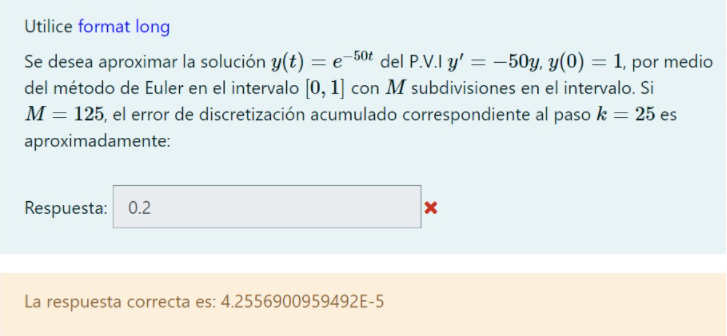

LO SÉ HACER, CALCULE ESA SOLUCION POR EULER, FIJESE EN LA 26 Y RESTE ESA 

EVALUADA EN LA SOLUCION

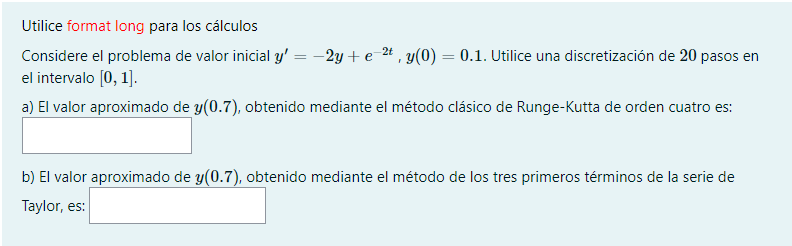

a=0;b=1;M=20; ya=0.1;
f= @(t,y) -2*y+exp(-2*t); ya=0.1;

ya = 0.1000

R = rk4 (f, a, b, ya, M) %a = 0.1935

R =          0    0.1000
    0.0500    0.1357
    0.1000    0.1637
    0.1500    0.1852
    0.2000    0.2011
    0.2500    0.2123
    0.3000    0.2195
    0.3500    0.2235
    0.4000    0.2247
    0.4500    0.2236


syms t y
f= -2*y+exp(-2*t)

$$f = {\mathrm{e}}^{-2\,t}-2\,y$$

 T = taylorN(f,3, a, b, ya, M) % B es 0.1973

T =          0    0.1000
    0.0500    0.1357
    0.1000    0.1638
    0.1500    0.1852
    0.2000    0.2011
    0.2500    0.2123
    0.3000    0.2196
    0.3500    0.2235
    0.4000    0.2247
    0.4500    0.2236


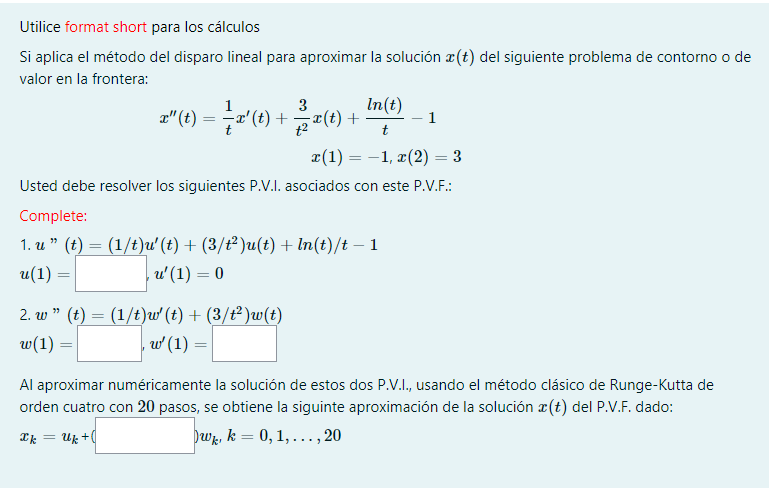

 format short
 

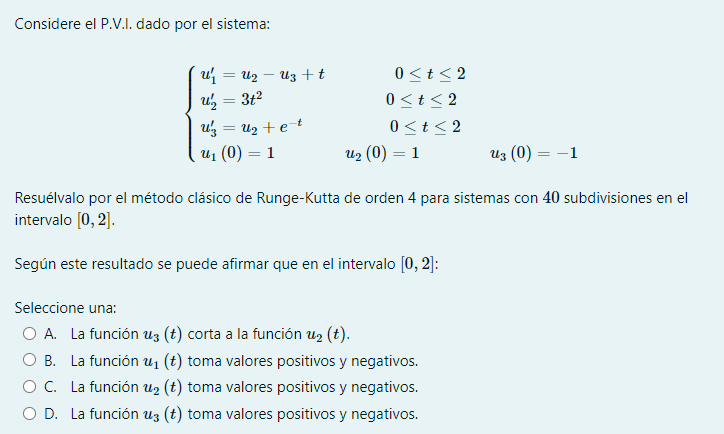

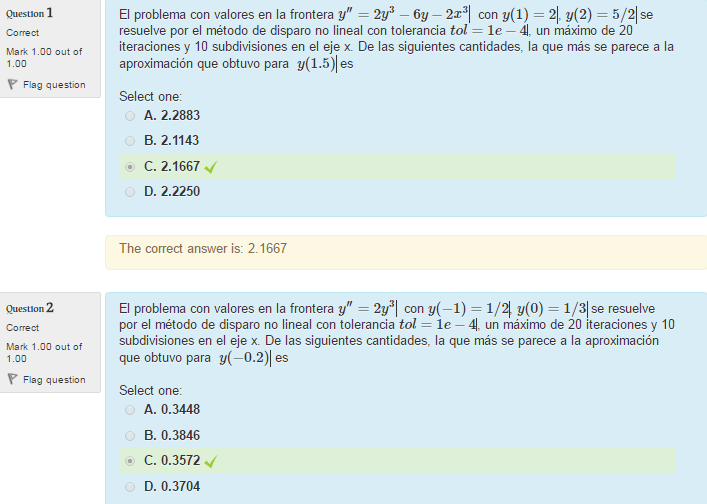

F = @(t,u) [u(2) ,2*u(1)^3-6*u(1)-2*t^3]

F = function_handle with value:
    @(t,u)[u(2),2*u(1)^3-6*u(1)-2*t^3]


G = @(t,u) [u(2),  2*u(1)^3-6*u(1)]

G = function_handle with value:
    @(t,u)[u(2),2*u(1)^3-6*u(1)]


F1 = [2 0]; G1 = [0 1]

G1 =      0     1


a=1;b=2; M = 10

M = 10

[T1, Z1] = rks4 (F, a, b, F1, M)

T1 =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


Z1 =     2.0000         0
    2.0091    0.1735
    2.0333    0.3055
    2.0692    0.4082
    2.1143    0.4896
    2.1667    0.5554
    2.2250    0.6091
    2.2882    0.6535
    2.3554    0.6906
    2.4261    0.7218


[T1, Z1] = rks4 (G, a, b, G1, M)

T1 =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


Z1 =          0    1.0000
    0.0990    0.9702
    0.1921    0.8831
    0.2739    0.7453
    0.3398    0.5662
    0.3862    0.3571
    0.4106    0.1298
    0.4119   -0.1040
    0.3900   -0.3326
    0.3459   -0.5443


 L = linsht (F, G, a, b, 2, 5/2, 20) % MELISIMO EL PRIMERO; SEGUNDO ES IGUAL

L =     1.0000    2.0000
    1.0500    2.0024
    1.1000    2.0091
    1.1500    2.0196
    1.2000    2.0334
    1.2500    2.0500
    1.3000    2.0693
    1.3500    2.0908
    1.4000    2.1143
    1.4500    2.1397


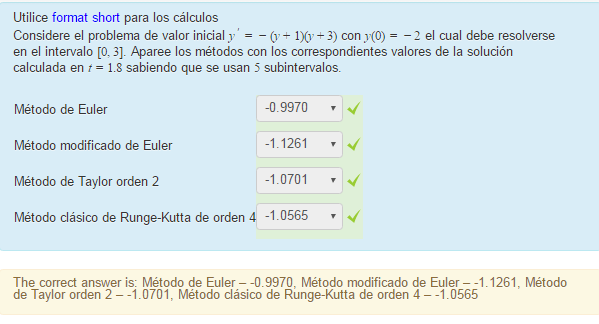

 f = @(t,y) -(y+1)*(y+3)

f = function_handle with value:
    @(t,y)-(y+1)*(y+3)


 a=0;b=3; M=5;Za=-2; %TYPE=
 AproxSol = vectorialSystem(f, a, b, -2, 5,"EulerMod") % MELO

AproxSol =          0   -2.0000
    0.6000   -1.5080
    1.2000   -1.2495
    1.8000   -1.1261
    2.4000   -1.0647
    3.0000   -1.0334


 
  AproxSol = vectorialSystem(f, a, b, -2, 5,"RK4")  % MELO

AproxSol =          0   -2.0000
    0.6000   -1.4637
    1.2000   -1.1696
    1.8000   -1.0565
    2.4000   -1.0182
    3.0000   -1.0058


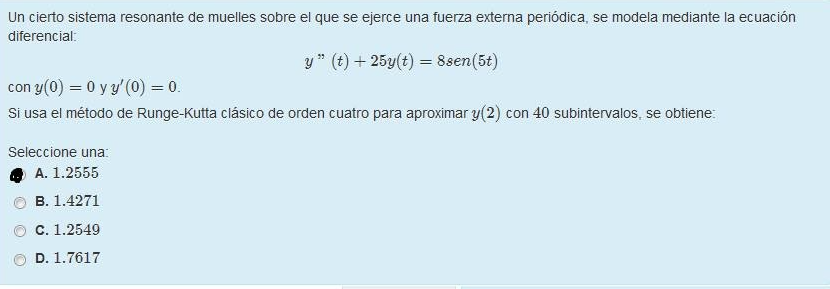

  a=0;b=2;M=40; Za=[0 0];
 F=@(t,u) [u(2), 8*sin(5*t)-25*u(1)];
 [T1, Z1] = rks4 (F, a, b, Za, 40)

T1 =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000


Z1 =          0         0
    0.0008    0.0495
    0.0065    0.1918
    0.0213    0.4090
    0.0482    0.6731
    0.0888    0.9489
    0.1426    1.1969
    0.2073    1.3775
    0.2786    1.4548
    0.3506    1.4005


 [T1',Z1] % 1.2555 MELISIMO

ans =          0         0         0
    0.0500    0.0008    0.0495
    0.1000    0.0065    0.1918
    0.1500    0.0213    0.4090
    0.2000    0.0482    0.6731
    0.2500    0.0888    0.9489
    0.3000    0.1426    1.1969
    0.3500    0.2073    1.3775
    0.4000    0.2786    1.4548
    0.4500    0.3506    1.4005


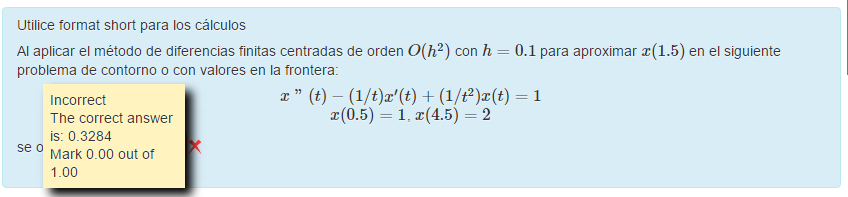

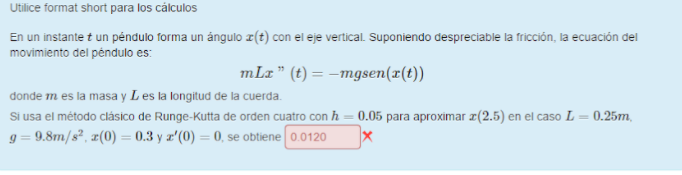

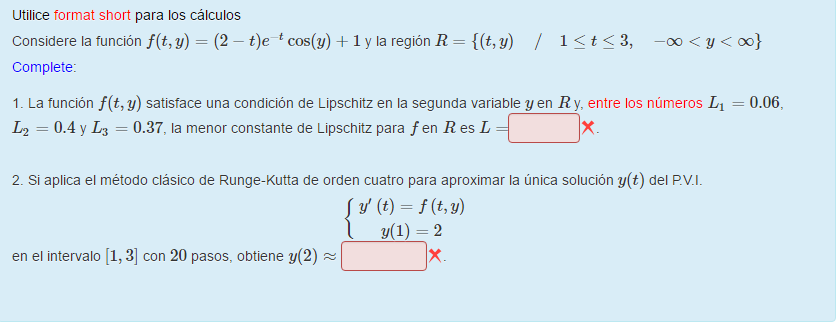

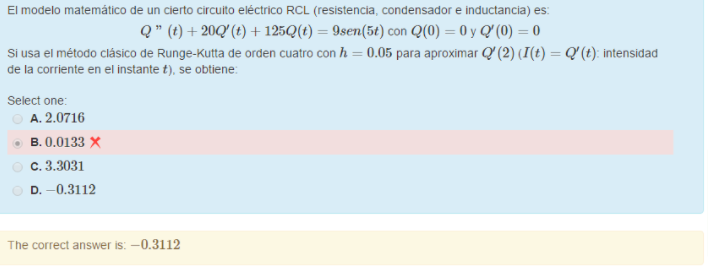

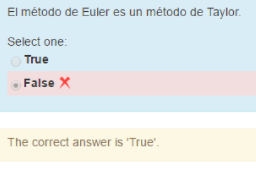

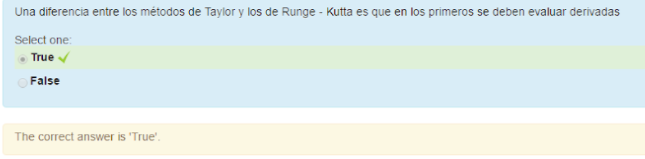

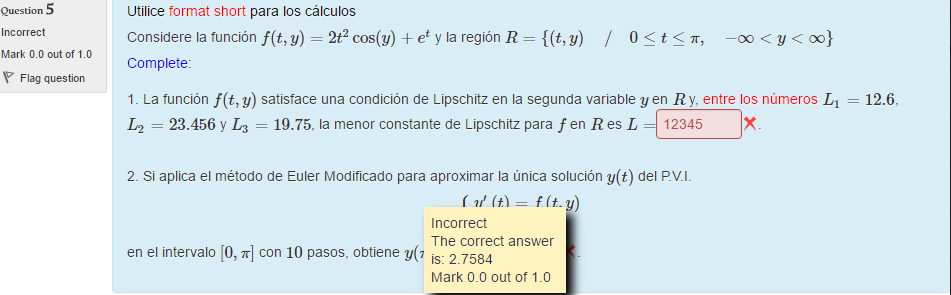

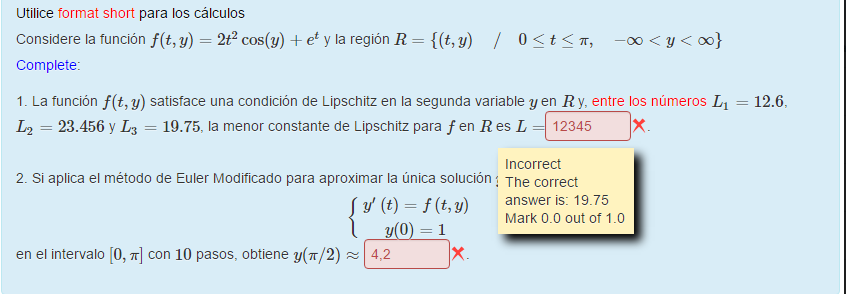

 f= @(t,u) [u(2), (2/t)*u(2)-2/t^2*u(1)+t*log(t) ]

f = function_handle with value:
    @(t,u)[u(2),(2/t)*u(2)-2/t^2*u(1)+t*log(t)]


 a=1;b=2; M=5, Za=[1 0]

M = 5

Za =      1     0


 [T, Z] = rks4 (f, a, b, Za, M) % -1.0921 para Y'

T =     1.0000    1.2000    1.4000    1.6000    1.8000    2.0000


Z =     1.0000         0
    0.9615   -0.3762
    0.8536   -0.6908
    0.6905   -0.9252
    0.4899   -1.0634
    0.2725   -1.0912


 [T',Z]

ans =     1.0000    1.0000         0
    1.2000    0.9615   -0.3762
    1.4000    0.8536   -0.6908
    1.6000    0.6905   -0.9252
    1.8000    0.4899   -1.0634
    2.0000    0.2725   -1.0912


 % 0.2725 para Y
 

f=@(t,y) (2/t)*y-2/t^2*y+t*log(t)

f = function_handle with value:
    @(t,y)(2/t)*y-2/t^2*y+t*log(t)


 f(2,-1.0921)

ans = 0.8402

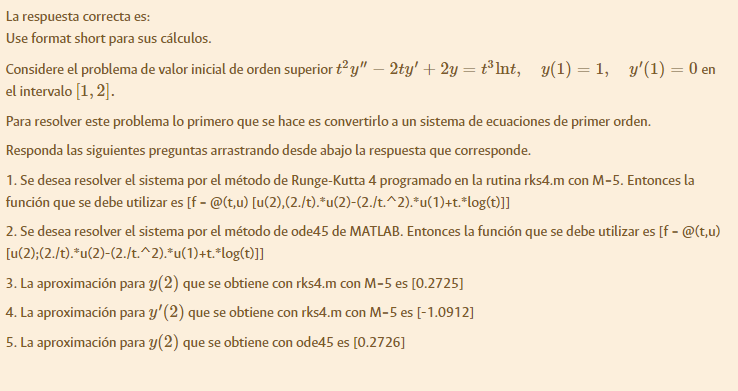

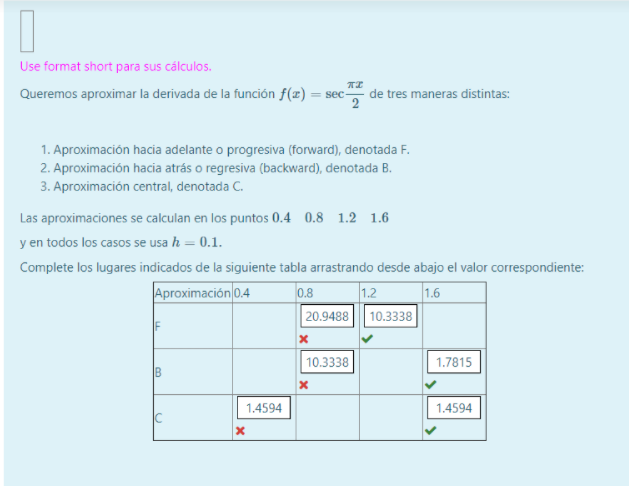

f = @(x) 2*x./(1+x.^2);
h= 0.1; a= 0.2; b= 1.8;

c= 1.8;

% Aproximacion Progesiva
F = (f(c+h)-f(c))/h

F = -0.2476


% Aproximacion regresiva
B = (f(c)-f(c-h))/h % Valio madres, no c xq esta mala SU MADRE!!!

B = -0.2498



% Aproximacion centrada

Cn = (f(c+h)-f(c-h))/(2*h)

Cn = -0.2487


% SD

sd =(f(c+h)-2*f(c)+f(c-h))./(h^2)

sd = 0.0218

f=@(x) sec(pi*x./2);
format short
h= 0.1; a= 0.4; b= 1.6;
f18p=(f(1.8+h)-f(1.8))/h

f18p = 0.3900

f18r=(f(1.8)-f(1.8-h))/h

f18r = 0.7086

f11r=(f(1.1)-f(1.1-h))/h

f11r = -1.6331e+17

f02c=(f(0.2+h)-f(0.2-h))/(2*h)

f02c = 0.5493

f06sd=(f(0.6+h)-2*f(0.6)+f(0.6-h))/(h^2)

f06sd = 21.4300

% Diferencias finitas tres tipos
syms x
f = sec(pi*x/2);
f = matlabFunction(f);

x0 = 0.4; h = 0.1;
% Diferencia progresiva
fpadelante = (f(x0+h)-f(x0))/h

fpadelante = 1.7815

% Diferencia regresiva 
fpatras = (f(x0)-f(x0-h))/h

fpatras = 1.1374

% Diferencia centrada para f'
fpcentrada = (f(x0+h)-f(x0-h))/(2*h)

fpcentrada = 1.4594

% DIferencia centrada para f''
fppcentrada = (f(x0+h)-2*f(x0)+f(x0-h))/(h^2)

fppcentrada = 6.4404